# 15.16 - General Numeric Solution

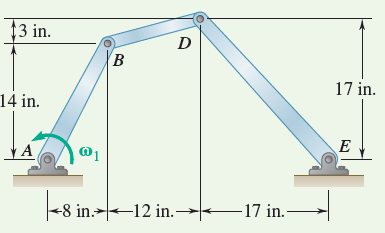

## Given                                          Find


$$\theta_A =f\left(t\right)\;$$
                                                         
$$\theta_B ,{\;\theta }_E ,\omega_B ,\omega_E ,\alpha_B ,\alpha_E$$


## Initialize variables and known quantities

dt = 0.01;
t = 0:dt:2*pi; % time vector from 0 to 10 in steps of dt

rAB = [8 14]
rBD = [12 3]
rED = [-17 17]
thetaA0 = atan(rAB(2) / rAB(1)) % initial value for thetaA
thetaB0 = atan(rBD(2) / rBD(1)) % initial value for thetaB
thetaE0 = atan(rED(2) / -rED(1)) % initial value for thetaE

thetaA = thetaA0 + sin(t)
omegaA = cos(t)
alphaA = -sin(t)

thetaB = zeros(1, length(t)); % zero vector of length t
omegaB = thetaB; % shortcut to assign it a zero vector
alphaB = thetaB;

thetaE = thetaB;
omegaE = thetaB;
alphaE = thetaB;

% add in initial values
thetaB(1) = thetaB0
thetaE(1) = thetaE0

## Analyze System for Missing Initial Values

We need to find: $\omega_{B_0 } ,\alpha_{B_0 } ,\omega_{E_0 } ,\alpha_{E_0 }$

sympref('FloatingPointOutput',true); % symbolic math setting
wb0 = sym('wb0'); % denotes 'wb0' as a symbolic variable
ab0 = sym('ab0');
we0 = sym('we0');
ae0 = sym('ae0');

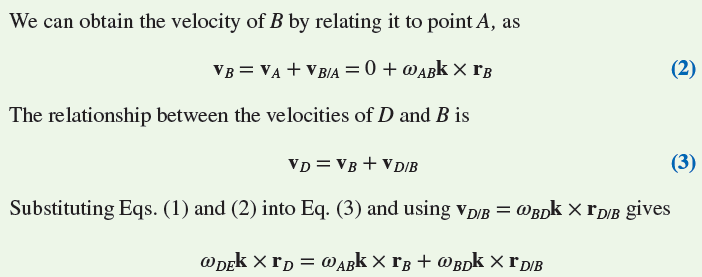

k = [0 0 1];
lhs = cross(we0*k, [rED 0])
rhs = cross(omegaA(1)*k, [rAB 0]) + cross(wb0*k, [rBD 0])
S = solve(lhs==rhs)
S.wb0
S.we0

% set first values in arrays to initial value
omegaB(1) = double(S.wb0)
omegaE(1) = double(S.we0)

Evaluate each term of the accleration equation separately

lhs = cross(ae0*k, [rED 0]) - omegaE(1)^2 * [rED 0]

ab = cross(alphaA(1)*k, [rAB 0]) - omegaA(1)^2 * [rAB 0]

adb = cross(ab0*k,[rBD 0]) - omegaB(1)^2 * [rBD 0]

combine for RHS and solve

rhs = ab + adb

S = solve(lhs == rhs)
alphaB(1) = double(S.ab0)
alphaE(1) = double(S.ae0)

We now have all initial values for the system!

## Simulate Stepping Through Time

At each time step $t_i$:

- calculate $\omega_i =\omega_{i-1} +\alpha_{i-1} \textrm{dt}$

- calculate $\theta_i =\theta_{i-1} +\omega_{i-1} \textrm{dt}+\frac{1}{2}\alpha_{i-1} {\textrm{dt}}^2$

- calculate $\alpha_i \;$using the above system of equations

- update rAB, rBD, rED

lrAB = norm(rAB); % get the length of rAB
lrBD = norm(rBD);
lrED = norm(rED);

for i = 2:length(t) % already have initial values, so start at second time step
    
    %update omegas
    omegaB(i) = omegaB(i-1) + alphaB(i-1)*dt;
    omegaE(i) = omegaE(i-1) + alphaE(i-1)*dt;
    
    %update thetas
    thetaB(i) = thetaB(i-1) + omegaB(i-1)*dt + 0.5*alphaB(i-1)*dt^2;
    thetaE(i) = thetaE(i-1) + omegaE(i-1)*dt + 0.5*alphaE(i-1)*dt^2;
    
    %update rAB, rBD, rED
     rAB = [lrAB*cos(thetaA(i)), lrAB*sin(thetaA(i))];
     rBD = [lrBD*cos(thetaB(i)), lrBD*sin(thetaB(i))];
     rED = [-lrED*cos(thetaE(i)), lrED*sin(thetaE(i))];
     
    %update alphas using system of equations
    lhs = cross(ae0*k, [rED 0]) - omegaE(i)^2 * [rED 0];
    ab = cross(alphaA(i)*k, [rAB 0]) - omegaA(i)^2 * [rAB 0];
    adb = cross(ab0*k,[rBD 0]) - omegaB(i)^2 * [rBD 0];
    rhs = ab + adb;
    S = solve(lhs == rhs);
    alphaB(i) = double(S.ab0);
    alphaE(i) = double(S.ae0);
end